# **InverseJacobiSC**

[Inverse of the Jacobi elliptic function sc](https://dlmf.nist.gov/22.15)

## Definition


$${\textrm{sc}}^{-1} \left(x\left|m\right.\right)\equiv \left\lbrace \begin{array}{cc}
\mathit{\mathbf{F}}\left(\frac{x}{\sqrt{1+x^2 }}\left|m\right.\right) & m\le 1\\
\frac{{\textrm{sd}}^{-1} \left(x\sqrt{m}\left|m^{-1} \right.\right)}{\sqrt{m}} & m>1
\end{array}\right.$$



$${\mathrm{sc}}^{-1} \left(x,k\right)\equiv {\mathrm{sc}}^{-1} \left(x\left|k^2 \right.\right)$$


where *m *is the parmeter, *k *is the modulus, $\mathit{\mathbf{F}}\left(x\left|m\right.\right)$ is  Jacobi form of the elliptic integral of the first kind.

Domain:   If $-\infty <m\le 1$ then $-\infty \le x\le \infty$ . If $m>1$ then $|x|<1/\sqrt{m-1}$.For the specified domain, the  codomain  is the set of real numbers.

Basic features:

${\mathrm{sc}}^{-1} \left(-x\left|m\right.\right)=-{\mathrm{sc}}^{-1} \left(x\left|m\right.\right)$   (odd)

Special values:

   
$${\mathrm{sc}}^{-1} \left(0\left|m\right.\right)=0$$


${\mathrm{sc}}^{-1} \left(x\left|0\right.\right)={\mathrm{tan}}^{-1} x$,    ${\mathrm{sc}}^{-1} \left(x\left|1\right.\right)={\mathrm{sinh}}^{-1} x$

Identities:


$${\mathrm{sc}}^{-1} \left(\mathrm{sc}\left(x\left|m\right.\right)\left|m\right.\right)=x,\;\;\;\;\left|x\right|<K\left(m\right)$$



$$\textrm{sc}\left({\textrm{sc}}^{-1} \left(x\left|m\right.\right)\left|m\right.\right)=x$$


$K\left(m\right)$ is the complete elliptic integral of the first kind .

## Syntax

Y = InverseJacobiSC(X,K)

y = ijsc(x,k)

Y = mInverseJacobiSC(X,M)

y = mijsc(x,m)

## Description

**Y = InverseJacobiSC(X,K)** return${\;\mathrm{sc}}^{-1} \left(x,k\right)$ for each element of the arrays X and K (modulus). X and K must be real and the ssce size or any of them can be scalar. **InverseJacobiSC** is the wrapper function which calls the functions **ijsc** element-wise via the function **ufun2**.

**y = ijsc(x,k)** return the value of ${\mathrm{sc}}^{-1} \left(x,k\right)$ for argument *x* and the modulus k. It is assumed that the input arguments are real scalars without check. y is NaN if any of   the input arguments is invalid or convergence failed. **ijsc** is the wrapper function which calls the functions **mijsc**.

**Y = mInverseJacobiSC(X,M)** returns ${\mathrm{sc}}^{-1} \left(x\left|m\right.\right)$ for each element of the arrays X and M (parsceter). X and M must be real and the ssce size or any of them can be scalar. **mInverseJacobiSC** is the wrapper function which calls the functions **mijsc** element-wise via the function **ufun2**.

**y = mijsc(x,m)** compute value of ${\mathrm{sc}}^{-1} \left(x\left|m\right.\right)$ for  argument x and the parsceter m. It is assumed that the input arguments are real scalars without check. y is NaN if any of  the input arguments is invalid or convergence failed.  **mijsc **call the function **melF **for calculation of ${\mathrm{sc}}^{-1} \left(x\left|m\right.\right)$ ([1-2]).

## Precision

## **Numerical Examples**

**Scalar input**

format long
k = 0.5;
x = 0.5;
[ijsc(x,k), InverseJacobiSC(x,k), mijsc(x,k^2), mInverseJacobiSC(x,k^2)]

ans =    0.467719051350593   0.467719051350593   0.467719051350593   0.467719051350593


% Maple 0.467719051350593_214


Accuracy.

fprintf('%.16g\n',mijsc(0.5,-4)) 

0.4159330998068017


%  Maple  0.4159330998068017_33

Special values

m=0.5;
disp(mijsc(0,m))  % m < 1 !!!

     0



disp(mijsc(1,m)-melF(1/sqrt(2),m))

     0



x=0.5;
disp(mijsc(x,0) - atan(x)) 

     0



disp(mijsc(x,1) - asinh(x))

     0



Identities

m = -2;
x = 0.5; % |x| <= 1
disp(mJacobiSC(mInverseJacobiSC(x,m),m)-x)

     2.220446049250313e-16




k = 0.99995;
x = 0.9999*elK(k);
disp(InverseJacobiSC(JacobiSC(x,k),k)-x)

     3.389999392311438e-11



m = 2; % m>1
x = 0.2; % x < sqrt(m-1)
disp(mijsc(x,m)-mijsd(x*sqrt(m),1/m)/sqrt(m))

     0



m = 0.5;
x = 0.2;
disp(mijsc(-x,m)+mijsc(x,m))

     0



**Vector input**

m = [0.1, 0.5, 0.89, 0.99995];
x = 0.2*ones(size(m));
disp(mJacobiSC(mInverseJacobiSC(x,m),m)-x)

   1.0e-16 *

  -0.555111512312578  -0.555111512312578   0.277555756156289                   0



**Matrix input**

m = [0.1, 0.5, 0.89; -1, -97, 0.99995 ]';
x = 0.2*ones(size(m));
disp(mJacobiSC(mInverseJacobiSC(x,m),m)-x)

   1.0e-15 *

  -0.055511151231258  -0.111022302462516
  -0.055511151231258  -0.083266726846887
   0.027755575615629                   0



## **Plot **

**Example 1**

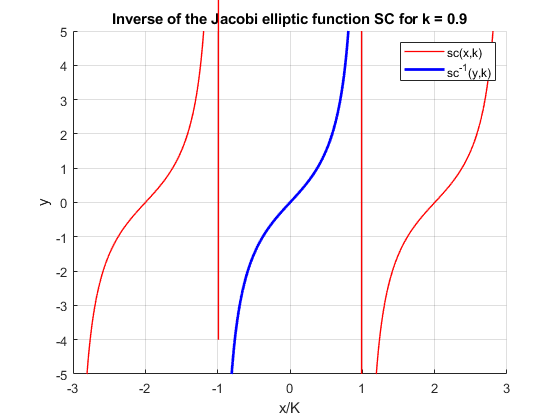

figure
hold on
x=-3:0.01:3;
k = 0.9;
M = elK(k);
plot(x,JacobiSC(M*x,k),'LineWidth',1.0,'Color','red')
x=-12:0.01:12;
plot(InverseJacobiSC(x,k)/M,x,'LineWidth',2,'Color','blue')
legend('sc(x,k)','sc^{-1}(y,k)') %,'Position','best')
xlabel('x/K')
ylabel('y')
%xlim([-1.1 1.1])
ylim([-5 5])
title(sprintf('Inverse of the Jacobi elliptic function SC for k = %g',k))
grid on
hold off

**Example 2**

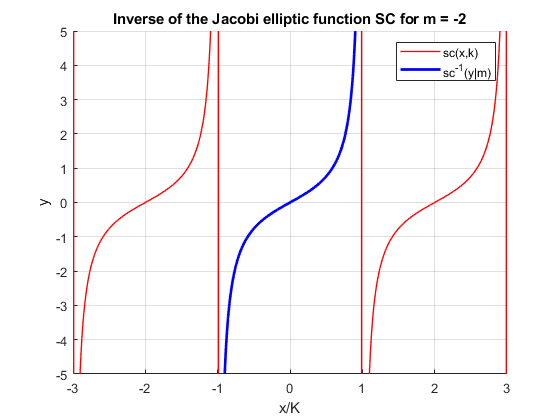

figure
hold on
x=-3:0.01:3;
m = -2;
if m < 1
    M = melK(m);
    xlabel('x/K')
elseif m > 1
    M = melK(1/m)/sqrt(m);
    xlabel('x/K')
else
    M = 1;
    xlabel('x')
end
plot(x,mJacobiSC(M*x,m),'LineWidth',1.0,'Color','red')
x=-12:0.01:12;
plot(mInverseJacobiSC(x,m)/M,x,'LineWidth',2,'Color','blue')
legend('sc(x,k)','sc^{-1}(y|m)') %,'Position','best')
ylabel('y')
%xlim([-1.1 1.1])
ylim([-5 5])
title(sprintf('Inverse of the Jacobi elliptic function SC for m = %g',m))
grid on
hold off

**Example 2**

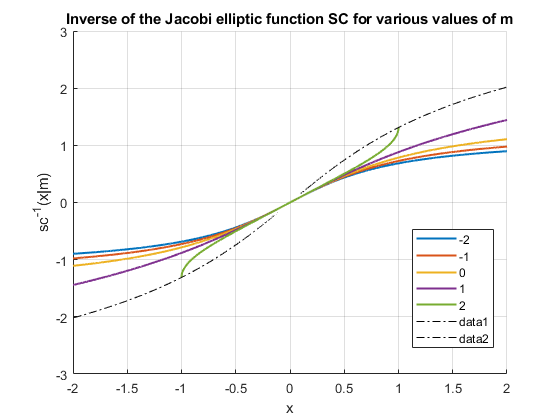

figure
hold on
X = -2:0.001:2;
M = [-2,-1,0,1,2];
SN = zeros(length(M),length(X));
clg{length(M)}=[];
for i = 1:length(M)
     clg{i} = num2str(M(i));
    SN(i,:) = mInverseJacobiSC(X,M(i));
end
plot(X,SN,'LineWidth',1.5)
axis([min(X) max(X) -3 3])
grid on
legend(clg{1:length(M)},'Location','Best')
title('Inverse of the Jacobi elliptic function SC for various values of m')
N=1:0.01:100;
X = 1./sqrt(N-1);
plot(X,mInverseJacobiSC(X,N),'k-.')
plot(-X,-mInverseJacobiSC(X,N),'k-.')
xlabel('x')
ylabel('sc^{-1}(x|m)')

**Example 3**

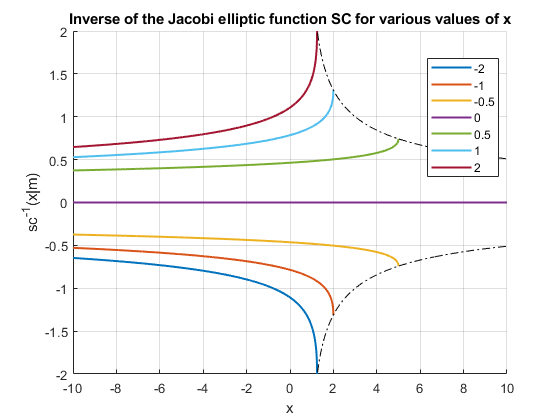

figure
hold on
M = -10:0.01:10;
X = [-2,-1,-0.5,0,0.5,1,2];
SN = zeros(length(X),length(M));
clg{length(X)}=[];
for i = 1:length(X)
     clg{i} = num2str(X(i));
    SN(i,:) = mInverseJacobiSC(X(i),M);
end
plot(M,SN,'LineWidth',1.5)
axis([min(M) max(M) -3 3])
ylim([-2  2])
grid on
legend(clg{1:length(X)},'Location','Best')
title('Inverse of the Jacobi elliptic function SC for various values of x')
xlabel('x')
ylabel('sc^{-1}(x|m)')
M = 1:0.01:10;
F = mInverseJacobiSC(1./sqrt(M-1),M);
plot(M,F,'k-.')
plot(M,-F,'k-.')
hold off

**Example 4**

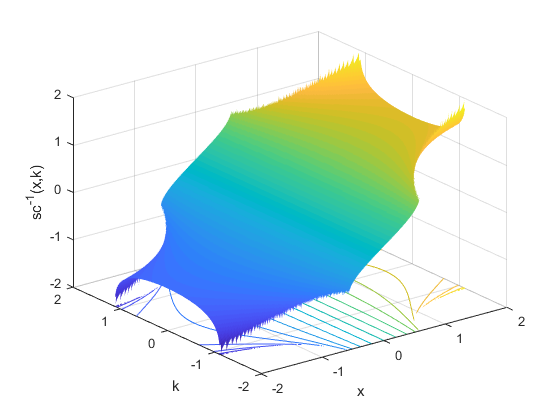

figure
x=-2:0.01:2;
k=-2:0.01:2;
zz = 2;
[X,M]=meshgrid(x,k);
hs=surfc(X,M,InverseJacobiSC(X,M),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = -zz;
hc.LineWidth = 0.5;
hc.LevelList = -zz:zz/10:zz;
view(3)
caxis([-zz zz])
xlabel('x')
ylabel('k')
zlabel('sc^{-1}(x,k)')
zlim([-zz zz])
grid on

**Example 4**

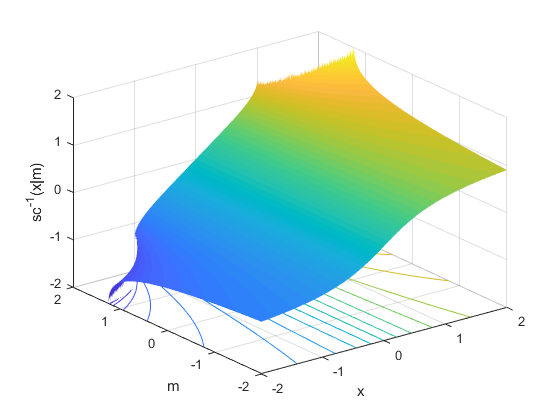

figure
x=-2:0.01:2;
m=-2:0.01:2;
zz = 2;
[X,M]=meshgrid(x,m);
hs=surfc(X,M,mInverseJacobiSC(X,M),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = -zz;
hc.LineWidth = 0.5;
hc.LevelList = -zz:zz/10:zz;
view(3)
caxis([-zz zz])
xlabel('x')
ylabel('m')
zlabel('sc^{-1}(x|m)')
zlim([-zz zz])
grid on

**Example 5**

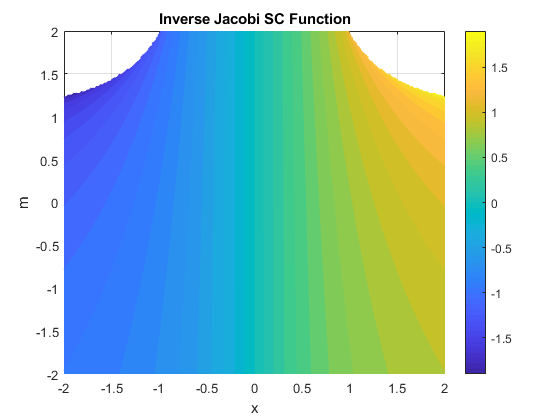

figure
f = @(x,m)mInverseJacobiSC(x,m);
fcontour(f,[-2 2 -2 2],'Fill','on','LevelList',-2:0.1:2,'MeshDensity',200)
title('Inverse Jacobi SC Function')
colorbar
xlabel('x')
ylabel('m')
grid on

**Example 6**

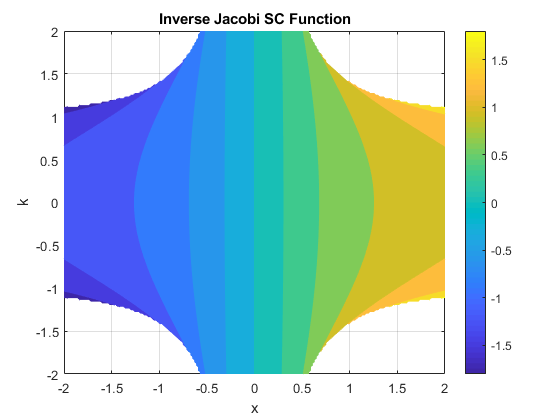

figure
f = @(x,k)InverseJacobiSC(x,k);
fcontour(f,[-2 2 -2 2],'Fill','on','LevelList',-3:0.3:3,'MeshDensity',200)
title('Inverse Jacobi SC Function')
colorbar
xlabel('x')
ylabel('k')
grid on

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Jacobian Elliptic Functions, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/22)

[Jacobi elliptic functions, Wikipedia](https://en.wikipedia.org/wiki/Jacobi_elliptic_functions)

## **References**

## See Also